close all

## Now we use periodogram to calc PSDs

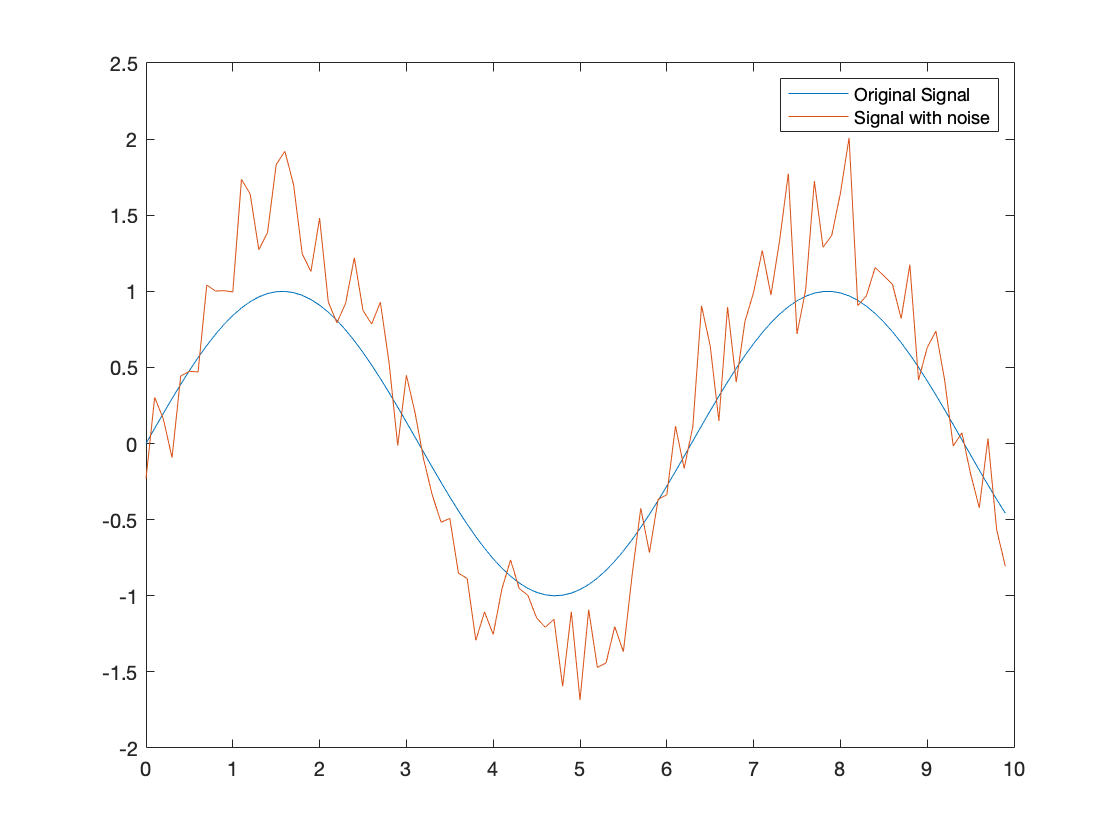

Fs = 10;
t = (0:1/Fs:10)'; %column vector
t = t(1:100);
target_snr = 10; %dB

x = sin(t); %audio signal -  clean sine wave, x
s = v_addnoise(x,Fs,target_snr); % degraded signal, s
n = s - x; %noise signal, n
figure
plot(t,[x s])
legend('Original Signal', 'Signal with noise')

%compute PSD using periodogram 
Ss = periodogram(s,rectwin(length(s)),length(s),Fs);
Nn = periodogram(n,rectwin(length(n)),length(n),Fs);
%Compute Wiener filter using different transfer function found
HH1 = Ss/(Ss+Nn);
HH1 = HH1 * exp(-1j*pi);
hh1 = ifft(HH1);
hh1 = hh1(:,3)

hh1 =   -0.0385 - 0.0000i
  -0.0346 - 0.0067i
  -0.0330 - 0.0135i
  -0.0286 - 0.0181i
  -0.0241 - 0.0234i
  -0.0194 - 0.0256i
  -0.0128 - 0.0274i
  -0.0079 - 0.0278i
  -0.0024 - 0.0271i
   0.0031 - 0.0261i


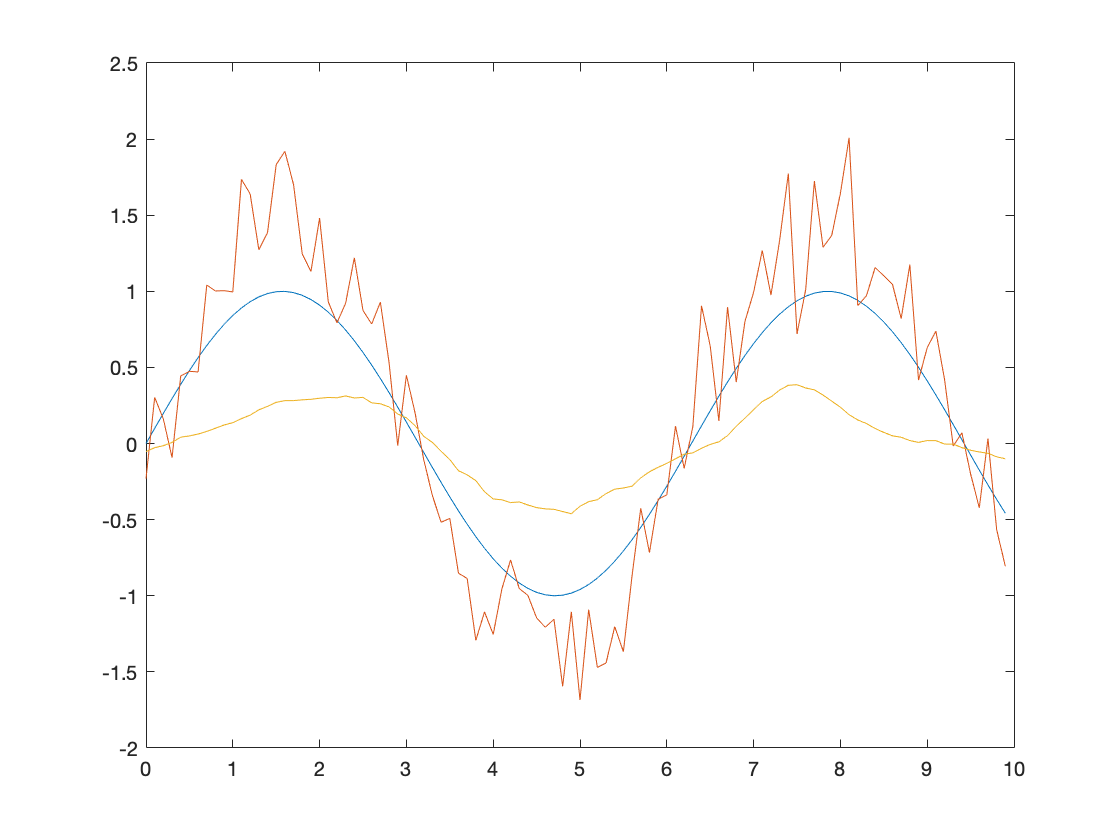

y = conv(s,hh1,'same');
figure;
plot(t,[x s y])

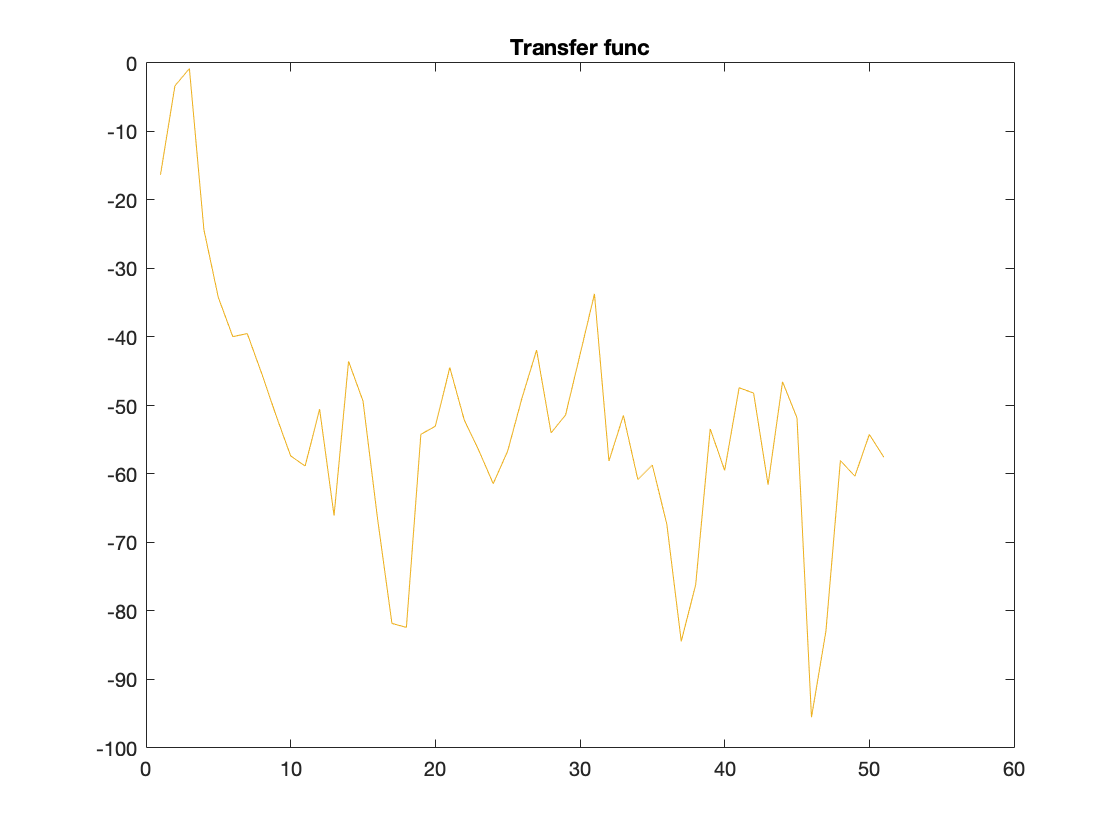

%%plot transfer function1 of wiener filter
figure;
plot(20*log10(abs(HH1)))
title('Transfer func')